I = im2gray(imread("blood.png"));
IE = edge(I,"prewitt");
[centers, radii, metric] = imfindcircles(IE, [5,10]);

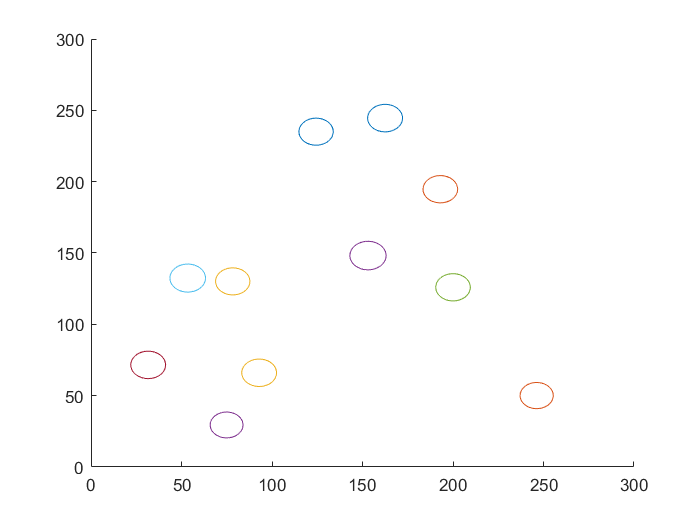

figure;
hold on;
for i = 1:size(centers, 1)
    cx = centers(i, 1);
    cy = centers(i, 2);
    r = radii(i, 1);
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + cx;
    yunit = r * sin(th) + cy;
    plot(xunit, yunit);
end

hold off;